# Plant

%Make sure to open the HybridSystemPerformance project.  This will set up
%paths correctly and clear the workspace.

plantPath = strcat(commonPath,'\Plant Model\');
latestPlant = latestTimeParse(plantPath,'plant');
load(latestPlant)
clear plantPath latestPlant

# Input Signals

inputPath = strcat(commonPath,'\Performance Input Signals\');
latestSlow = latestTimeParse(inputPath,'performanceInputsSlow');
latestFast = latestTimeParse(inputPath,'performanceInputsFast');
latestPureSin = latestTimeParse(inputPath,'pureSin');
load(latestSlow)
load(latestFast)
clear inputPath latestSlow latestFast
load(latestPureSin)
clear inputPath latestSlow latestFast latestPureSin

# Globals

delta_t = t(2)-t(1);
delta_pureSinTime = pureSinTime(2)-pureSinTime(1);
KpStatic = 1;
KiStatic = 10;
tdStatic=0.04;

# Toggles

togRMSFreq = 1;

# Model

%Model Setup
tend = num2str(pureSinTime(end));
stepsize = num2str(delta_pureSinTime);
simName = 'HybridSaccadeFF';

load_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize,'FastRestart','on') %'SimulationMode','accelerator','SimCompilerOptimization','on'
save_system(simName)

# RMSE as a function of frequency and switching threshold

if togRMSFreq == 1  
    %First, the smooth system using lsim
    Kp = 3:1:10;
    for j = 1:length(Kp)
        Ki = KiStatic;
        td =tdStatic;
        smoothRMSE = simRMSE(Kp(j),Ki,td,0,0,G_plant,pureSin,pureSinTime,sinfreqs,[],'');
        
        %Next, Hybrid System with Infinite switching threshold (should match
        %pure smooth system)
        tLimSet = struct('T_lim_up',inf,'T_lim_low',-inf);
        hybridInfRMSE = simRMSE(Kp(j),Ki,td,inf,1,G_plant,pureSin,pureSinTime,sinfreqs,tLimSet,simName);
        %Animation
        basepath = strcat(commonPath,'\Hybrid Performance Results');
        fig=figure('Position', [100, 100, 1024, 1200]);
        clear F
        switchThreshRange = 0:0.2:10;
        for i = 1:length(switchThreshRange)
            tic
            hybridTempRMSE = simRMSE(Kp(j),Ki,td,switchThreshRange(i),1,G_plant,pureSin,pureSinTime,sinfreqs,tLimSet,simName);  
            plot(sinfreqs,smoothRMSE,'k',sinfreqs,hybridInfRMSE,'.r',sinfreqs,hybridTempRMSE,'b')
            title(sprintf('K_p = %.1f, K_i = %.1f, Switch Threshold = %.1f',Kp(j),Ki,switchThreshRange(i)))
            legend('Smooth Lsim','Smooth Simulink','Hybrid')
            F(i) = getframe(fig);
            toc
        end
        v = VideoWriter(strcat(basepath,'\rmseFreqSwitchVideo_Kp_',num2str(Kp(j)),'_Ki_',num2str(Ki),'.avi'));
        v.FrameRate = 2;
        open(v)
        writeVideo(v,F);
        close(v)  
    end
    
        Ki = 1:1:10;
    for j = 1:length(Ki)
        Kp = KpStatic;
        td =tdStatic;
        smoothRMSE = simRMSE(Kp,Ki(j),td,0,0,G_plant,pureSin,pureSinTime,sinfreqs,[],'');
        
        %Next, Hybrid System with Infinite switching threshold (should match
        %pure smooth system)
        tLimSet = struct('T_lim_up',inf,'T_lim_low',-inf);
        hybridInfRMSE = simRMSE(Kp,Ki(j),td,inf,1,G_plant,pureSin,pureSinTime,sinfreqs,tLimSet,simName);
        %Animation
        basepath = strcat(commonPath,'\Hybrid Performance Results');
        fig=figure('Position', [100, 100, 1024, 1200]);
        clear F
        switchThreshRange = 0:0.2:10;
        for i = 1:length(switchThreshRange)
            tic
            hybridTempRMSE = simRMSE(Kp,Ki(j),td,switchThreshRange(i),1,G_plant,pureSin,pureSinTime,sinfreqs,tLimSet,simName);  
            plot(sinfreqs,smoothRMSE,'k',sinfreqs,hybridInfRMSE,'.r',sinfreqs,hybridTempRMSE,'b')
            title(sprintf('K_p = %.1f, K_i = %.1f, Switch Threshold = %.1f',Kp,Ki(j),switchThreshRange(i)))
            legend('Smooth Lsim','Smooth Simulink','Hybrid')
            F(i) = getframe(fig);
            toc
        end
        v = VideoWriter(strcat(basepath,'\rmseFreqSwitchVideo_Kp_',num2str(Kp),'_Ki_',num2str(Ki(j)),'.avi'));
        v.FrameRate = 2;
        open(v)
        writeVideo(v,F);
        close(v)  
    end
   
    
    
    

%     figure
%     plot(sinfreqs,smoothRMSE,'k',sinfreqs,hybridInfRMSE,'.r')
%     lgd{1} = 'Smooth Lsim';
%     lgd{2} = 'Smooth Simulink';
%     hold on
%     switchThreshRange = [2.5 2.8 3 3.3 3.8 4 4.5];
%     for i = 1:length(switchThreshRange)
%         hybridTempRMSE = simRMSE(Kp,Ki,td,switchThreshRange(i),1,G_plant,pureSin,pureSinTime,sinfreqs,tLimSet,simName);  
%         plot(sinfreqs,hybridTempRMSE)
%         lgd{2+i} = strcat('Hybrid - Switch Threshold = ',num2str(switchThreshRange(i)));
%     end
%     
%     xlabel('Input Sin Frequency (Hz)')
%     ylabel('RMSE (deg/s)')
%     legend(lgd,'Location','northwestoutside')
%     hold off   
end

# Sweep across switching threshold

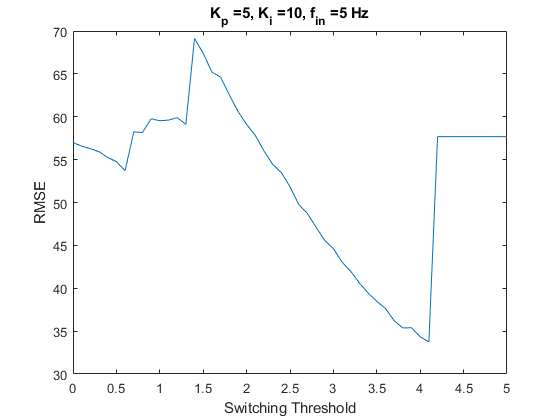

%Input
fin = 50;
V_in = [pureSinTime' pureSin(fin,:)'];

%Parameters
sac_time = 0.04; %Saccade completion "delay"
n_delay = .04; %Neurological Delay
T_lim_up = inf; %Biological Torque Limit upper
T_lim_low = -inf; %Biological Torque Limit upper
K_P = 5; %Proportional Gain
K_I = 10; %Integral Gain of smooth system


switch_threshbig = 0:0.1:5; %Integrated error threshold for switching between smooth/saccadic
rmse = zeros(1,length(switch_threshbig));
for i = 1:size(switch_threshbig,2)
    switch_thresh = switch_threshbig(i);
    out = sim('HybridSaccadeFF.slx','AlgebraicLoopMsg', 'off');
    rmse(i) = sqrt(mean((out.V_out-V_in(:,2)).^2));
end

figure
plot(switch_threshbig,rmse)

ylabel('RMSE')
xlabel('Switching Threshold')
title(strcat('K_p =',num2str(K_P),', K_i = ',num2str(K_I),', f_{in} = ',num2str(sinfreqs(fin)),' Hz'))

# Optimal Point Gain Sweep

Prange = 1:1:15;
Irange = 1:1:15;
switchrange = 0.5:0.5:10;
freqrange = 1:1:5;
estimatedTimeHrs = (.035*numel(Prange)*numel(Irange)*numel(switchrange)*numel(freqrange))/3600
estimatedTimeMins = (.035*numel(Prange)*numel(Irange)*numel(switchrange)*numel(freqrange))/60
estimatedTimeSecs = (.035*numel(Prange)*numel(Irange)*numel(switchrange)*numel(freqrange))/1

%Parameters
sac_time = 0.04; %Saccade completion "delay"
n_delay = .04; %Neurological Delay
T_lim_up = inf; %Biological Torque Limit upper
T_lim_low = -inf; %Biological Torque Limit upper

%Input
%V_in = [t' sos'];

% %Parallel Simulation Setup
% tic
% numSims = size(switchrange,2)*size(Prange,2)*size(Irange,2);
% clear simIn
% simIn(1:numSims) = Simulink.SimulationInput(simName);
% 
% iter = 1;
% for i = 1:size(Prange,2)
%     for j = 1:size(Irange,2)
%         for k = 1:size(switchrange,2) 
%             %Constants
%             simIn(iter) = simIn(iter).setVariable('sac_time',sac_time,'Workspace',simName);
%             simIn(iter) = simIn(iter).setVariable('n_delay',n_delay,'Workspace',simName);
%             simIn(iter) = simIn(iter).setVariable('T_lim_up',T_lim_up,'Workspace',simName);
%             simIn(iter) = simIn(iter).setVariable('T_lim_low',T_lim_low,'Workspace',simName);
%             simIn(iter) = simIn(iter).setVariable('G_plant',G_plant,'Workspace',simName);
%             simIn(iter) = simIn(iter).setVariable('V_in',V_in,'Workspace',simName);
%             
%             %Variables
%             simIn(iter) = simIn(iter).setVariable('switch_thresh',switchrange(k),'Workspace',simName);
%             simIn(iter) = simIn(iter).setVariable('K_P',Prange(i),'Workspace',simName);
%             simIn(iter) = simIn(iter).setVariable('K_I',Irange(j),'Workspace',simName);
%             
%             iter = iter + 1;
%         end
%         
%     end
% end
% out = parsim(simIn,'UseFastRestart','on');
% toc

tic
minswitch = zeros(size(freqrange,2),size(Prange,2)*size(Irange,2),3);
error = zeros(1,size(switchrange,2));
iter=1;
for l = 1:size(freqrange,2)
   puresine = 50*sin(2*pi*freqrange(l)*t);
   V_in = [t' puresine'];
   for i = 1:size(Prange,2)
    for j = 1:size(Irange,2)
        K_P = Prange(i);
        K_I = Irange(j);

        for k = 1:size(switchrange,2)
            switch_thresh = switchrange(k);
            out = sim('HybridSaccadeFF.slx');
            error(k) = sum(abs(sos'-out.V_out));
        end
        
        [minerror,index] = min(error);
        minswitch(l,iter,:) = [K_P K_I switchrange(index)];
        iter=iter+1;
    end  
    end 
end

toc

filename1 = strcat('ch','_',num2str(scale),'_',num2str(f_start),'_',num2str(f_end),'_');
filename2 = strcat('ssf','_',num2str(f(1)),'_',num2str(f(2)),'_',num2str(f(3)),'_');
filename3 = strcat('ssp','_',num2str(p(1)),'_',num2str(p(2)),'_',num2str(p(3)),'_');
filename4 = strcat('kp','_',num2str(Prange(1)),'_',num2str(Prange(2)-Prange(1)),'_',num2str(Prange(end)),'_');
filename5 = strcat('ki','_',num2str(Irange(1)),'_',num2str(Irange(2)-Irange(1)),'_',num2str(Irange(end)),'_');
filename6 = strcat('sw','_',num2str(switchrange(1)),'_',num2str(switchrange(2)-switchrange(1)),'_',num2str(switchrange(end)));
filename7 = strcat('sw','_',num2str(freqrange(1)),'_',num2str(freqrange(2)-freqrange(1)),'_',num2str(freqrange(end)));
filename = strcat(filename1,filename2,filename3,filename4,filename5,filename6,'.mat')
save(filename,'minswitch','chirps','sos','scale')


for i = 1:size(freqrange,2)
    figure('Renderer', 'painters', 'Position', [10 10 1000 700])
    set(gcf, 'Color', 'w');
    sf = fit([minswitch(i,:,1)', minswitch(i,:,2)'],minswitch(i,:,3)','cubicinterp');
    plot(sf)
end




ax = gca;
ax.XAxis.FontSize = 12;
ax.XAxis.FontName = 'Segoe UI';
ax.YAxis.FontSize = 12;
ax.YAxis.FontName = 'Segoe UI';
ax.ZAxis.FontSize = 12;
ax.ZAxis.FontName = 'Segoe UI';
xlabel('K_P','FontName','Segoe UI Semibold','FontSize',14)
ylabel('K_I','FontName','Segoe UI Semibold','FontSize',14)
zlabel('Optimum Switching Threshold','FontName','Segoe UI Semibold','FontSize',14)
box on
view(-30,25)
